%% Step Counter using Accelerometer Data

%% Load Data
accelData = randn(1000,1) + 1;

%% Preprocess Data
windowSize = 5;
smoothedData = movmean(accelData, windowSize);

%% Step Detection
stepThreshold = 0.5;
[pks, locs] = findpeaks(smoothedData, 'MinPeakHeight', stepThreshold);
numSteps = length(locs);

%% Display Results
fprintf('Total Steps Counted: %d\n', numSteps);

Total Steps Counted: 218


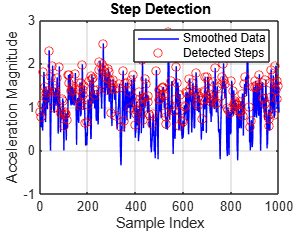


%% Plot Results
figure;
plot(smoothedData, 'b'); hold on;
plot(locs, pks, 'ro');
xlabel('Sample Index');
ylabel('Acceleration Magnitude');
title('Step Detection');
legend('Smoothed Data', 'Detected Steps');
grid on;